clearvars
close all
clc

***LITHIUM-ION BATTERY 0-D ELECTROCHEMICAL ANALYTICAL MODEL***

Author: F. L. E. Usseglio-Viretta, Center for Energy Conversion & Storage Systems, NREL

# ***Purpose and main assumptions***

    This is a very simple lithium-ion battery (LIB) model used to have an insight of the concentration and potential typical values and evolutions within a LIB during cycling. Its other purpose is to help validating numerical models when used in the exact same conditions and geometry.

    The geometry considered is a row of dense anode (no porosity), dense electrolyte (no solid), and dense cathode (no porosity) of thickness $L_a ,L_e$ and $L_c$, respectively. Note that within a real LIB cell, the anode and cathode are porous materials, filled with electrolyte, so this geometry is not representative. Each domain is represented with a concentration $C$ and a potential $\phi$. **We assume diffusivity and conductivity to be infinite**, therefore within each domain concentration and potential are uniform, and the model become 0-D. Height $h$ and width $w$ are introduced for the sole purpose to work with a volume for each domain, to better keep track of the problem dimensionality.

    A current $G\;$is applied on one extremity of the cell, while a fixed potential $\phi_{\textrm{ref}}$ is applied on the other extremity, on the solid phases only (extremites are noted $\Gamma$). The sign of the current determines if the cell is charging ($C_{s,a} \nearrow ,C_{s,c} \searrow ,$) or discharing ($C_{s,a} \searrow ,C_{s,c} \nearrow$). In both cases, due to mass conservation the electrolyte concentration $C_e$ is unchanged. The electrochemical reaction current density $j_{\textrm{me}} \;$at the anode-electrolyte interface $I_{\textrm{ae}}$ and at the cathode-electrolyte interface $I_{\textrm{ce}}$ is modeled according to a Butler-Volmer equation.

    This model **range of validity **corresponds to at least one of the following conditions:

- Near-zero applied current

- Very thin electrodes and separator

- Extremly high diffusivity and conductivity in solids and electrolyte

The above conditions enforce each domain have uniform potential and concentration.

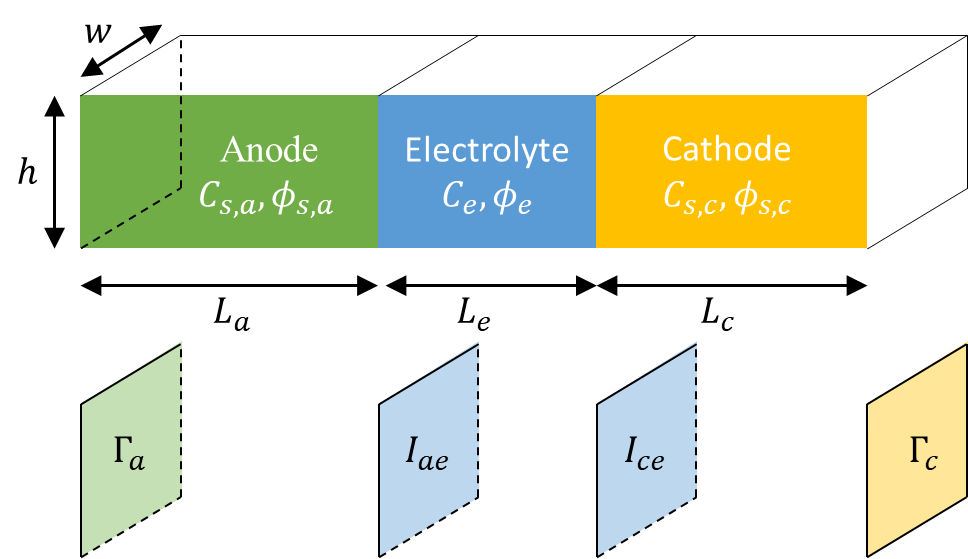

# ***Model***

Since diffusivity and conductivity are assumed infinite, there is no need to model conservation equations.

## Electrochemical reaction

The current density at the interface active material-electrolyte interface $j_{\textrm{me}}$ (subscript m is either a for anode or c for cathode) is:

$j_{\textrm{me}} =i_{0,m} \left(e^{\frac{F}{2\textrm{RT}}\eta_m } -e^{\frac{-F}{2\textrm{RT}}\eta_m } \right)\;\left\lbrack A\ldotp m^{-2} \right\rbrack$. Forward and reverse reaction are symmetrical (1/2).

with:

$i_{0,m} =f\left(C_{s,m} ,C_e \right)\;\left\lbrack A\ldotp m^{-2} \right\rbrack$ the exchange current density.

$\eta_m =\phi_{s,m} -\phi_e -{\textrm{OCP}}_m \;\left\lbrack V\right\rbrack$ the overpotential.

${\textrm{OCP}}_m =f\left(C_{s,m} \right)\;\left\lbrack V\right\rbrack \;$the open circuit potential, which is the potential difference $\phi_{s,m} -\phi_e$ when no current is applied.

The concentration flux at the active material - electrolyte interfaces $I_{\textrm{me}}$ are:


$$\bar{N_m } \ldotp \bar{n} =\frac{j_{\textrm{me}} }{F}\left\lbrack \textrm{mol}\ldotp s^{-1} \ldotp m^{-2} \right\rbrack$$


The potential flux at the active material - electrolyte interfaces $I_{\textrm{me}}$ are:


$$\bar{j_m } \ldotp \bar{n} =j_{\textrm{me}} \;\left\lbrack C\ldotp s^{-1} \ldotp m^{-2} \right\rbrack$$


## Current density

- Electrode capacity:

$\Phi_m^{\textrm{theoritical}} =\Omega_m C_{s,m\;\max } F\;\left\lbrack C\right\rbrack$, the electrode capacity if all the state of charge range (0 to 1) is used.

$\Phi_m^{\textrm{pratical}} =\Phi_m^{\textrm{theoritical}} \left({\textrm{SOC}}_m^{\max } -{\textrm{SOC}}_m^{\min } \right)\;\left\lbrack C\right\rbrack$, the electrode capacity is in pratical limited to a certain state of charge range due to crystallographic instability.

$C_{s,m} ={\textrm{SOC}}_m C_{s,m\;\max } \left\lbrack \textrm{mol}\ldotp m^{-3} \right\rbrack$, defintion of state of charge.

$F\left\lbrack C\ldotp {\textrm{mol}}^{-1} \right\rbrack$ is the Faraday constant. $\Omega_m \left\lbrack m^3 \right\rbrack$ is the electrode solid volume. $C_{s,m\;\max } \left\lbrack \textrm{mol}\ldotp m^{-3} \right\rbrack$ is the electrode solid material maximum (saturation) concentration.${\textrm{SOC}}_m^{\max } \left\lbrack 0,1\right\rbrack$ and ${\textrm{SOC}}_m^{\min } \;\left\lbrack 0,1\right\rbrack$  are, respectively, the maximum and minimum state of charge. Electrode material may not be able to use the theortical maximum state of charge range due to due to crystallographic instability at either low or high state of charge.

- Cell capacity and N/P ratio:

$\Phi_{\textrm{cell}} =\min \left(\Phi_a^{\textrm{pratical}} ,\Phi_c^{\textrm{pratical}} \right)\left\lbrack C\right\rbrack$, the cell capacity.

$N/P=\frac{\Phi_a^{\textrm{pratical}} }{\Phi_c^{\textrm{pratical}} }$, the N/P ratio should be > 1 (the cell capacity is limited by the cathode capacity). This is to take into account some lithium will be lost in the anode due to side reactions (SEI growth). Therefore a larger reservoir of lithium is requried in the cathode side.

- Applied current at the current collector $\Gamma_a$ and $\Gamma_c$

$t_{\textrm{charge}} =\frac{3600\;}{C_{\textrm{rate}} }\left\lbrack s\right\rbrack$, the time to charge fully the cell.

$G_{1C} =\frac{\Phi_{\textrm{cell}} }{3600}\left\lbrack C\ldotp s^{-1} =A\right\rbrack$, the current to charge in 1h (i.e., for $C_{\textrm{rate}} =1$).

$G=G_{1C} C_{\textrm{rate}} \left\lbrack A\right\rbrack$, the current to charge with the applied C-rate.

$g_m =\frac{G}{S_{\Gamma_m } }\left\lbrack A\ldotp m^{-2} \right\rbrack$ the applied current density at the interface solid electrode - current collector. $S_{\Gamma_m } \left\lbrack m^2 \right\rbrack$ is the interface area area solid electrode - current collector. 

- Current density at the active interface $I_{\textrm{ae}}$ and $I_{\textrm{ce}}$

The balance equation below is implicit, and is a consequence of the potential incompressibility. It is used to deduce the current density at the active interface.


$$\underset{\Gamma_a }{\int \int g_a \;\textrm{ds}=} \underset{I_{\textrm{ae}} }{\int \int j_{\textrm{ae}} } \;\textrm{ds}=\underset{I_{\textrm{ce}} }{\int \int j_{\textrm{ce}} } \;\textrm{ds}\underset{\Gamma_c }{\;=\int \int g_c } \;\textrm{ds}=G$$


Therefore:

$\left\langle j_{\textrm{me}} \right\rangle =\frac{G}{S_{I_{\textrm{me}} } }\left\lbrack A\ldotp m^{-2} \right\rbrack$ the average current density at the active material - electrolyte interface. $S_{I_{\textrm{me}} } \left\lbrack m^2 \right\rbrack$ is the interface area active material - electrolyte interface. Since the problem is 0D, $\left\langle j_{\textrm{me}} \right\rangle =j_{\textrm{me}}$.

Because the potential flux and concentration flux are identical modulo the Faraday constant, the balance equation implies the gain (loss) of lithium in the anode is equal to the loss (gain) of lithium in the cathode, with a zero gain in the electrolyte and in the cell.

## Problem initialization

- Concentrations:

Initial concentrations, $C_{s,a}^{\textrm{t0}} ,C_{s,c}^{\textrm{t0}}$ and $C_e^{\textrm{t0}}$ are known ($C_e^{\textrm{t0}}$ is often noted $C_{e,\textrm{at}\;\textrm{rest}}$).


$$C_{s,m}^{\textrm{t0}} ={\textrm{SOC}}_m^{\textrm{t0}} C_{s,m\;\max } \left\lbrack \textrm{mol}\ldotp m^{-3} \right\rbrack$$


- Potentials:

$j_{\textrm{me}} ={2i}_{0,m} \sinh \left(\frac{F}{2\textrm{RT}}\eta_m \right)\;\left\lbrack A\ldotp m^{-2} \right\rbrack$, therefore: $\eta_m =\phi_{s,m} -\phi_e -{\textrm{OCP}}_m =\frac{2\textrm{RT}}{F}\textrm{asinh}\left(\frac{j_{\textrm{me}} }{{2i}_{0,m} }\right)$

Since $j_{\textrm{me}}$ is known the only unknowns are $\phi_{s,m} -\phi_e$. Since one electrode is gounded - let's say we ground the anode, then we can deduce the electrolyte potential and then the cathode potential.


$$\phi_{s,a}^{\textrm{t0}} =\phi_{\textrm{ref}}$$



$$\phi_e^{\textrm{t0}} =\phi_{s,a}^{\textrm{t0}} -{\textrm{OCP}}_a -\frac{2\textrm{RT}}{F}\textrm{asinh}\left(\frac{j_{\textrm{ae}} }{{2i}_{0,a} }\right)$$



$$\phi_c^{\textrm{t0}} =\phi_e^{\textrm{t0}} +{\textrm{OCP}}_c +\frac{2\textrm{RT}}{F}\textrm{asinh}\left(\frac{j_{\textrm{ce}} }{{2i}_{0,c} }\right)$$


## Problem evolution

### Concentration variation

The concentration flux at the active material - electrolyte interfaces $I_{\textrm{me}}$, $\bar{N_m } \ldotp \bar{n}$, provide the concentration variation. Per unit of time, the concentration variation is equal to:


$$\Delta \textrm{mol}=\frac{j_{\textrm{me}} }{F}S_{I_{\textrm{me}} } \left\lbrack \textrm{mol}\ldotp s^{-1} \right\rbrack$$


if charging:

$C_{s,a}^t =C_{s,a}^{t+\textrm{dt}} +\frac{\Delta \textrm{mol}\;\textrm{dt}}{\Omega_m }$, $C_{s,c}^t =C_{s,c}^{t+\textrm{dt}} -\frac{\Delta \textrm{mol}\;\textrm{dt}}{\Omega_m }$

If discharging:

$C_{s,a}^t =C_{s,a}^{t+\textrm{dt}} -\frac{\Delta \textrm{mol}\;\textrm{dt}}{\Omega_m }$, $C_{s,c}^t =C_{s,c}^{t+\textrm{dt}} +\frac{\Delta \textrm{mol}\;\textrm{dt}}{\Omega_m }$

### Potential variation

Because the problem is 0D, we can reuse the same method for potential initialization.

## Post-processing

Several metrics are typically calculated:

- Cell voltage (or cell terminal potential): the difference between the average potential at cell extremities (cathode - anode): $\frac{\underset{\Gamma_c }{\;\int \int \phi_{s,c} } \;\textrm{ds}}{\underset{\Gamma_c }{\;\int \int 1} \;\textrm{ds}}-\frac{\underset{\Gamma_a }{\;\int \int \phi_{s,a} } \;\textrm{ds}}{\underset{\Gamma_a }{\;\int \int 1} \;\textrm{ds}}$

            During charging, the cell voltage is increasing. High value can trigger electrolyte degradation, therefore when such threshold is reach (called cut-off voltage), the applied current is decreased to keep the cell voltage constant. For a standard graphite/NMC LIB cell, the cutoff voltage is between 4.1 and 4.2 V.

- Potential for lithium plating. During charging, the anode-electrolyte potential difference $\phi_{s,a} -\phi_e$ at the active interface is decreasing. If it goes below zero, a side-reaction named lithium-plating, become thermodynamically favorable. Lithium, instead of intercalating within the crystallographic structure of the graphite, is depositing at the graphite surface and forms a thin solid metal layer. The as-deposited lithium may block future reaction, as  formerly active suface is covered, and if plating reaction is not reversed during discharging (the reverse reaction is called lithium stripping), it's a loss of lithium that results in capacity fade. 

# ***Parameters***

- Dimensions (in micrometers):

La=35; % um
Le=10; % um
Lc=25; % um
h=1; % um
w=1; % um

Table_dimension = table([La;h;w],[Le;h;w],[Lc;h;w],...
    'VariableNames',{'Anode' 'Electrolyte' 'Cathode'},'RowNames',{'Thickness (um)';'Height (um)';'Width (um)'});
disp(Table_dimension);

                      Anode    Electrolyte    Cathode
                      _____    ___________    _______

    Thickness (um)     35          10           25   
    Height (um)         1           1            1   
    Width (um)          1           1            1   



- Electrolyte concentration

Ce_to =1200; % [mol.m-3]
fprintf('\n    Electrolyte concentration = %1.2f mol.m-3\n',Ce_to);


    Electrolyte concentration = 1200.00 mol.m-3


- Anode material coefficients and intial state of charge

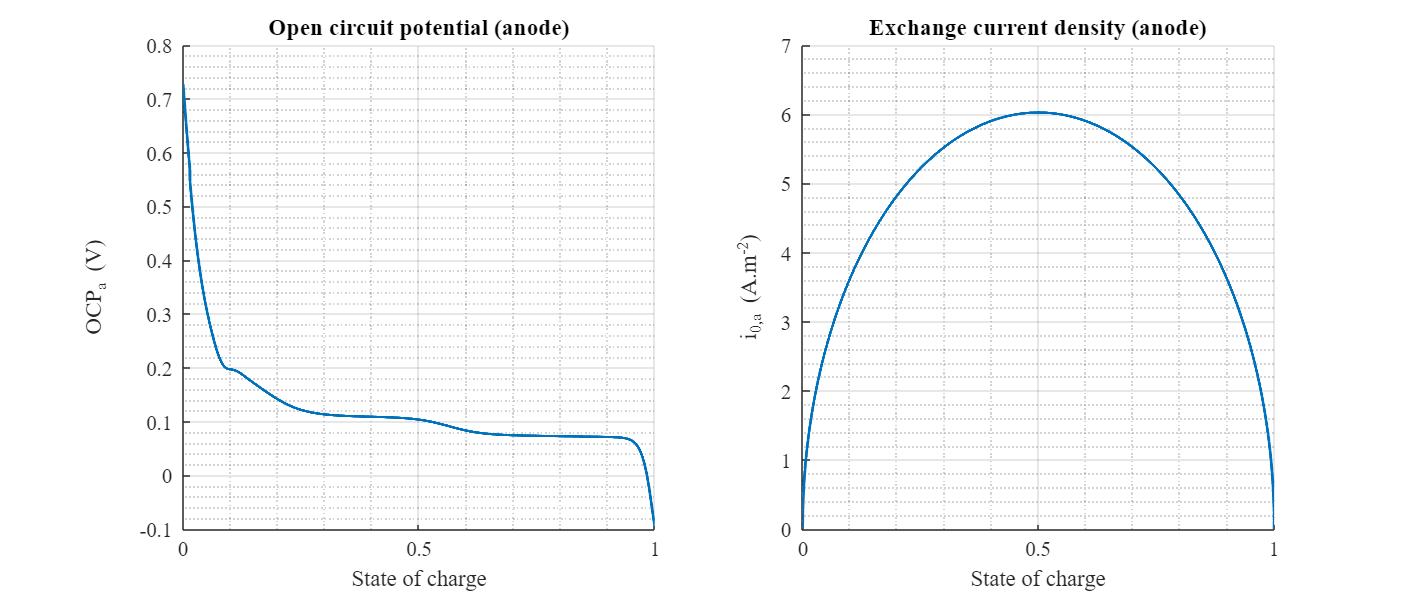

Csmax_anode=28000; % [mol.m-3]
anode_soc_min=0.001;
anode_soc_max=0.999;
anode_soc_to =0.001;
anode_io="Graphite (symmetric)";
anode_OCP="Graphite";

scrsz = get(0,'ScreenSize'); % Screen resolution
% Plot parameters
c=linspace(0,Csmax_anode,1e4);
ocp = zeros(1,1e4); io = zeros(1,1e4);
for k=1:1:1e4
    ocp(k) = OCP_a_fct(c(k),Csmax_anode,anode_OCP);
    io(k) = Io_a_fct(c(k),Csmax_anode,Ce_to,Ce_to,anode_io);
end
Fig = figure; % Create figure
Fig.Name= 'Open circuit potential and exchange current density (anode)'; % Figure name
Fig.Color='white'; % Background colour
set(Fig,'position',[scrsz(1) scrsz(2) scrsz(3)*2/3 scrsz(4)/2]); % Full screen figure
for id_axe=1:1:2
    if id_axe==1
        sub_axes=subplot(1,2,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Open circuit potential (anode)'); % Set title font
        plot(c/Csmax_anode,ocp,'Linewidth',2,'DisplayName','Anode');
        ylabel('OCP_{a} (V)');
    elseif id_axe==2
        sub_axes=subplot(1,2,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Exchange current density (anode)'); % Set title font
        plot(c/Csmax_anode,io,'Linewidth',2,'DisplayName','Anode');
        ylabel('i_{0,a} (A.m^{-2})');
    end
    xlabel('State of charge');
    % - Grid
    grid(sub_axes,'on'); % Display grid
    set(sub_axes,'XMinorGrid','on','YMinorGrid','on'); % Display grid for minor thicks
    set(sub_axes,'FontName','Times new roman','FontSize',14); % Fontname and fontsize
    h_title.FontSize = 16; % Set title fontsize
    h_legend.FontSize = 14; % Set title fontsize
    hold(sub_axes,'off'); % Relase figure
end

- Cathode material coefficients and intial state of charge

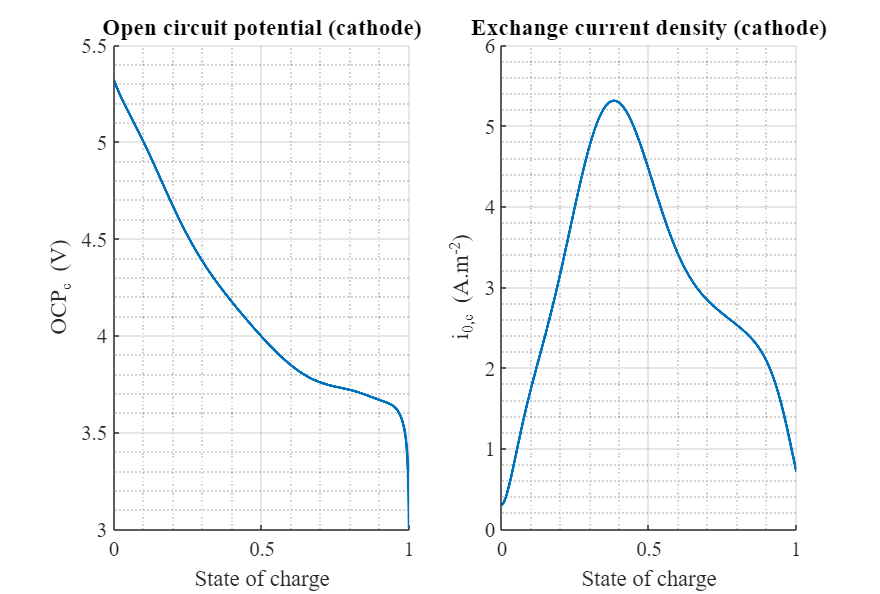

Csmax_cathode=49600; % [mol.m-3]
cathode_soc_min=0.4;
cathode_soc_max=0.999;
cathode_soc_to =0.999;
cathode_io="NMC (asymmetric)";
cathode_OCP="NMC";

% Plot parameters
c=linspace(0,Csmax_cathode,1e4);
ocp = zeros(1,1e4); io = zeros(1,1e4);
for k=1:1:1e4
    ocp(k) = OCP_c_fct(c(k),Csmax_cathode,cathode_OCP);
    io(k) = Io_c_fct(c(k),Csmax_cathode,Ce_to,Ce_to,cathode_io);
end
Fig = figure; % Create figure
Fig.Name= 'Open circuit potential and exchange current density (cathode)'; % Figure name
Fig.Color='white'; % Background colour
set(Fig,'position',[scrsz(1) scrsz(2) scrsz(3)*2/3 scrsz(4)/2]); % Full screen figure
for id_axe=1:1:2
    if id_axe==1
        sub_axes=subplot(1,2,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Open circuit potential (cathode)'); % Set title font
        plot(c/Csmax_cathode,ocp,'Linewidth',2,'DisplayName','Anode');
        ylabel('OCP_{c} (V)');
    elseif id_axe==2
        sub_axes=subplot(1,2,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Exchange current density (cathode)'); % Set title font
        plot(c/Csmax_cathode,io,'Linewidth',2,'DisplayName','Anode');
        ylabel('i_{0,c} (A.m^{-2})');
    end
    xlabel('State of charge');
    % - Grid
    grid(sub_axes,'on'); % Display grid
    set(sub_axes,'XMinorGrid','on','YMinorGrid','on'); % Display grid for minor thicks
    set(sub_axes,'FontName','Times new roman','FontSize',14); % Fontname and fontsize
    h_title.FontSize = 16; % Set title fontsize
    h_legend.FontSize = 14; % Set title fontsize
    hold(sub_axes,'off'); % Relase figure
end

Table_SOC = table([Csmax_anode;anode_soc_min;anode_soc_max;anode_soc_to],[Csmax_cathode;cathode_soc_min;cathode_soc_max;cathode_soc_to],...
    'VariableNames',{'Anode' 'Cathode'},'RowNames',{'Cs max (mol.m-3)';'Minimum state of charge';'Maximum state of charge';'Initial state of charge'});
disp('State of charge and solid concentration:');

State of charge and solid concentration:


disp(Table_SOC);

                               Anode    Cathode
                               _____    _______

    Cs max (mol.m-3)           28000     49600 
    Minimum state of charge    0.001       0.4 
    Maximum state of charge    0.999     0.999 
    Initial state of charge    0.001     0.999 



- Grounded electrode

phi_ref=0; % [V]
electrode_grounded="Anode";
fprintf('\n    Electrode grounded is %s, with a fixed potential = %1.2f V\n',electrode_grounded,phi_ref);


    Electrode grounded is Anode, with a fixed potential = 0.00 V


- C-rate (applied current)

The time required to fully charge or discharge the cell is equal to 1/C.

Crate=0.1;
Cell_is="charging";
fprintf('\n    C-rate = %1.2f, cell is %s\n',Crate,Cell_is);


    C-rate = 0.10, cell is charging


- Temperature

Temp=293.15; % [K]
fprintf('\n    Temperature = %1.2f K\n',Temp);


    Temperature = 293.15 K


# ***Calculation***

## Initialization

% Physical constant
Fday = 96487.0; % [C.mol-1]
Rgas = 8.31446261815324; % [J.mol-1.K-1]

% Volumes
volume_anode = La*1e-6*h*1e-6*w*1e-6; % [m3]
volume_electolyte = Le*1e-6*h*1e-6*w*1e-6; % [m3]
volume_cathode = Lc*1e-6*h*1e-6*w*1e-6; % [m3]
volume_cell = volume_anode+volume_electolyte+volume_cathode; % [m3]

% Electrode Capacity
theoritical_capacity_anode = volume_anode * Csmax_anode * Fday; % [C]
pratical_capacity_anode = theoritical_capacity_anode * (anode_soc_max-anode_soc_min); %  [C]
theoritical_capacity_cathode = volume_cathode * Csmax_cathode * Fday; % [C]
pratical_capacity_cathode = theoritical_capacity_cathode * (cathode_soc_max-cathode_soc_min); %  [C]

% Cell pratical capacity
pratical_capacity_cell = min(pratical_capacity_anode, pratical_capacity_cathode); % [C]

% N/P ratio (ratio of anode capacity over cathode capacity). Must be > 1
Cell_NP_ratio = pratical_capacity_anode/pratical_capacity_cathode;

Table_capacity = table({volume_anode;theoritical_capacity_anode;pratical_capacity_anode;'n/a'},...
    {volume_electolyte;'n/a';'n/a';'n/a'},...
    {volume_cathode;theoritical_capacity_cathode;pratical_capacity_cathode;'n/a'},...
    {volume_cell;'n/a';pratical_capacity_cell;Cell_NP_ratio},...
    'VariableNames',{'Anode' 'Electrolyte' 'Cathode' 'Cell'},'RowNames',{'Volume (m3)';'Theoritical capacity (C)';'Pratical capacity (C)';'N/P ratio'});
disp('Capacity:');

Capacity:


disp(Table_capacity)

                                    Anode          Electrolyte         Cathode             Cell     
                                ______________    ______________    ______________    ______________

    Volume (m3)                 {[3.5000e-17]}    {[1.0000e-17]}    {[2.5000e-17]}    {[7.0000e-17]}
    Theoritical capacity (C)    {[9.4557e-08]}    {'n/a'       }    {[1.1964e-07]}    {'n/a'       }
    Pratical capacity (C)       {[9.4368e-08]}    {'n/a'       }    {[7.1667e-08]}    {[7.1667e-08]}
    N/P ratio                   {'n/a'       }    {'n/a'       }    {'n/a'       }    {[    1.3168]}



if Cell_NP_ratio<1
    disp('Warning: N/P ratio is below one!')
end

% Applied current
time_to_charge = 3600/Crate; % [s]
Current1C = pratical_capacity_cell/3600; % [A=C.s-1] Current for 1C
Applied_current_G = Current1C * Crate; % [A]

% Applied current density
surface_anodesolid_currentcollector = h*1e-6*w*1e-6; % [m2]
surface_cathodsolid_currentcollector = h*1e-6*w*1e-6; % [m2]
Applied_current_density_anode_ga = Applied_current_G/surface_anodesolid_currentcollector; % [A.m-2]
Applied_current_density_cathode_gc = Applied_current_G/surface_cathodsolid_currentcollector; % [A.m-2]

% Current density at the active interface
surface_anodesolid_electrolyte = h*1e-6*w*1e-6; % [m2]
surface_cathodesolid_electrolyte = h*1e-6*w*1e-6; % [m2]
Activeinterface_current_density_anode_j_ae = Applied_current_G /surface_anodesolid_electrolyte;
Activeinterface_current_density_cathode_j_ce = Applied_current_G / surface_cathodesolid_electrolyte;

Table_current = table([Applied_current_G;Applied_current_density_anode_ga],...
    [Applied_current_G;Activeinterface_current_density_anode_j_ae],...
    [Applied_current_G;Activeinterface_current_density_cathode_j_ce],...
    [Applied_current_G;Applied_current_density_cathode_gc],...
    'VariableNames',{'CC-Anode' 'Anode-electrolyte' 'Electrolyte-cathode' 'Cathode-CC'},'RowNames',{'Current (A)';'Current density (A.m-2)'});
disp('Current:');

Current:


fprintf('\n    C-rate = %1.2f, time to charge = %1.2f s,\n',Crate,time_to_charge);


    C-rate = 0.10, time to charge = 36000.00 s,


disp(Table_current)

                                CC-Anode     Anode-electrolyte    Electrolyte-cathode    Cathode-CC
                               __________    _________________    ___________________    __________

    Current (A)                1.9907e-12       1.9907e-12            1.9907e-12         1.9907e-12
    Current density (A.m-2)        1.9907           1.9907                1.9907             1.9907




% Concentration initialization
Cs_a_to = anode_soc_to*Csmax_anode;
Cs_c_to = cathode_soc_to*Csmax_cathode;

% Potential initialization
if strcmp(electrode_grounded,'Anode')
    phis_anode_to = phi_ref;

    io = Io_a_fct(Cs_a_to,Csmax_anode,Ce_to,Ce_to,anode_io);
    eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_anode_j_ae/(2*io));
    phie_to = phis_anode_to - OCP_a_fct(Cs_a_to,Csmax_anode,anode_OCP) - eta;

    io = Io_c_fct(Cs_c_to,Csmax_cathode,Ce_to,Ce_to,cathode_io);
    eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_cathode_j_ce/(2*io));
    phis_cathode_to = eta + phie_to + OCP_c_fct(Cs_c_to,Csmax_cathode,cathode_OCP);
elseif strcmp(electrode_grounded,'Cathode')
    phis_cathode_to = phi_ref;

    io = Io_c_fct(Cs_c_to,Csmax_cathode,Ce_to,Ce_to,cathode_io);
    eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_cathode_j_ce/(2*io));
    phie_to = phis_cathode_to - OCP_c_fct(Cs_c_to,Csmax_cathode,cathode_OCP) - eta;

    io = Io_a_fct(Cs_a_to,Csmax_anode,Ce_to,Ce_to,anode_io);
    eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_anode_j_ae/(2*io));
    phis_anode_to = eta + phie_to + OCP_a_fct(Cs_a_to,Csmax_anode,anode_OCP);
end

Table_initialization = table([Cs_a_to;phis_anode_to],[Ce_to;phie_to],[Cs_c_to;phis_cathode_to],...
       'VariableNames',{'Anode' 'Electrolyte' 'Cathode'},'RowNames',{'Concentration (mol.m-3)';'Potential (V)'});
disp('Initialization:');

Initialization:


disp(Table_initialization)

                               Anode    Electrolyte    Cathode
                               _____    ___________    _______

    Concentration (mol.m-3)     28           1200       49550 
    Potential (V)                0       -0.80188      2.3591 




% Time calculation
ntime=1000;
t = linspace(0,time_to_charge,ntime); % [s]
Cs_a_t = zeros(ntime,1); Phi_a_t = zeros(ntime,1);
C_e_t = zeros(ntime,1); Phi_e_t = zeros(ntime,1);
Cs_c_t = zeros(ntime,1); Phi_c_t = zeros(ntime,1);
Cell_voltage = zeros(ntime,1);
PotentialPlating = zeros(ntime,1);

Cs_a_t(1)=Cs_a_to; Phi_a_t(1)=phis_anode_to;
C_e_t(1)=Ce_to; Phi_e_t(1)=phie_to;
Cs_c_t(1)=Cs_c_to; Phi_c_t(1)=phis_cathode_to;
Cell_voltage(1) = phis_cathode_to-phis_anode_to;
PotentialPlating(1) = phis_anode_to-phie_to;

for k=2:1:ntime
    % Concentration variation
    dt = t(k)-t(k-1); % [s]
    dmol = Activeinterface_current_density_anode_j_ae/Fday*surface_anodesolid_electrolyte*dt; % [mol]
    dC_anode = dmol/volume_anode;
    dC_cathode = dmol/volume_cathode;
    if strcmp(Cell_is,'charging')
        Cs_a_t(k) = Cs_a_t(k-1) + dC_anode;
        Cs_c_t(k) = Cs_c_t(k-1) - dC_cathode;
    elseif strcmp(Cell_is,'discharging')
        Cs_a_t(k) = Cs_a_t(k-1) - dC_anode;
        Cs_c_t(k) = Cs_c_t(k-1) + dC_cathode;
    end
    C_e_t(k) = C_e_t(k-1);

    % Potential variation
    if strcmp(electrode_grounded,'Anode')
        Phi_a_t(k) = phi_ref;

        io = Io_a_fct(Cs_a_t(k),Csmax_anode,C_e_t(k),Ce_to,anode_io);
        eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_anode_j_ae/(2*io));
        Phi_e_t(k) = Phi_a_t(k) - OCP_a_fct(Cs_a_t(k),Csmax_anode,anode_OCP) - eta;

        io = Io_c_fct(Cs_c_t(k),Csmax_cathode,C_e_t(k),Ce_to,cathode_io);
        eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_cathode_j_ce/(2*io));
        Phi_c_t(k) = eta + Phi_e_t(k) + OCP_c_fct(Cs_c_t(k),Csmax_cathode,cathode_OCP);
    elseif strcmp(electrode_grounded,'Cathode')
        Phi_c_t(k) = phi_ref;

        io = Io_c_fct(Cs_c_t(k),Csmax_cathode,C_e_t(k),Ce_to,cathode_io);
        eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_cathode_j_ce/(2*io));
        Phi_e_t(k) = Phi_c_t(k) - OCP_c_fct(Cs_c_t(k),Csmax_cathode,cathode_OCP) - eta;

        io = Io_a_fct(Cs_a_t(k),Csmax_anode,C_e_t(k),Ce_to,anode_io);
        eta = 2*Rgas*Temp/Fday*asinh(Activeinterface_current_density_anode_j_ae/(2*io));
        Phi_a_t(k) = eta + Phi_e_t(k) + OCP_a_fct(Cs_a_t(k),Csmax_anode,anode_OCP);
    end

    % Cell voltage
    Cell_voltage(k) = Phi_c_t(k)-Phi_a_t(k);
    % Potential for lithium plating
    PotentialPlating(k) = Phi_a_t(k)-Phi_e_t(k);

end


## Degree of Freedoms, concentrations and potentials:

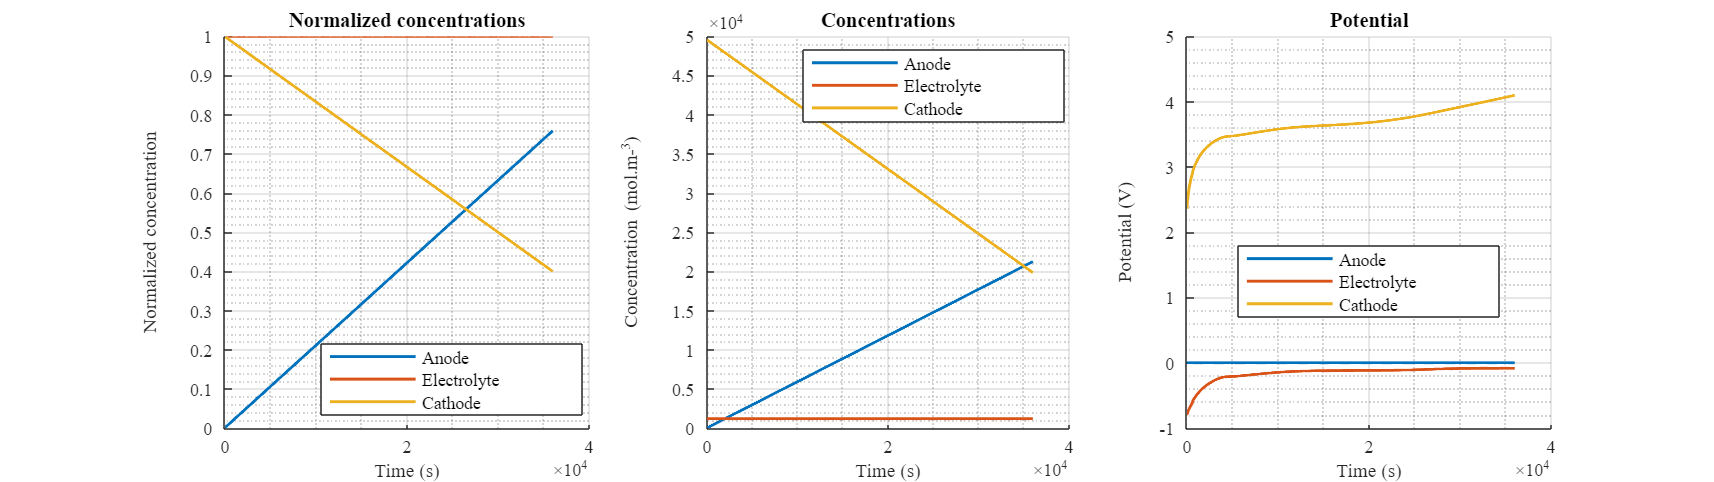

% Concentration, normalized concentration, and potential
Fig = figure; % Create figure
Fig.Name= 'Concentration and potential'; % Figure name
Fig.Color='white'; % Background colour
set(Fig,'position',[scrsz(1) scrsz(2) scrsz(3)*1 scrsz(4)/2]); % Full screen figure
for id_axe=1:1:3
    if id_axe==1
        sub_axes=subplot(1,3,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Normalized concentrations'); % Set title font
        plot(t,Cs_a_t/Csmax_anode,'Linewidth',2,'DisplayName','Anode');
        plot(t,C_e_t/Ce_to,'Linewidth',2,'DisplayName','Electrolyte');
        plot(t,Cs_c_t/Csmax_cathode,'Linewidth',2,'DisplayName','Cathode');
        ylabel('Normalized concentration');
    elseif id_axe==2
        sub_axes=subplot(1,3,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Concentrations'); % Set title font
        plot(t,Cs_a_t,'Linewidth',2,'DisplayName','Anode');
        plot(t,C_e_t,'Linewidth',2,'DisplayName','Electrolyte');
        plot(t,Cs_c_t,'Linewidth',2,'DisplayName','Cathode');   
        ylabel('Concentration (mol.m-^{3})');
    elseif id_axe==3
        sub_axes=subplot(1,3,id_axe,'Parent',Fig); hold(sub_axes,'on'); % Active subplot
        h_title=title ('Potential'); % Set title font    
        plot(t,Phi_a_t,'Linewidth',2,'DisplayName','Anode');
        plot(t,Phi_e_t,'Linewidth',2,'DisplayName','Electrolyte');
        plot(t,Phi_c_t,'Linewidth',2,'DisplayName','Cathode');     
        ylabel('Potential (V)');
    end
    xlabel('Time (s)');
    % Legend
    h_legend = legend(sub_axes,'Location','best');
    % - Grid
    grid(sub_axes,'on'); % Display grid
    set(sub_axes,'XMinorGrid','on','YMinorGrid','on'); % Display grid for minor thicks
    set(sub_axes,'FontName','Times new roman','FontSize',12); % Fontname and fontsize
    h_title.FontSize = 14; % Set title fontsize
    h_legend.FontSize = 12; % Set title fontsize
    hold(sub_axes,'off'); % Relase figure
end

## Post-processing:

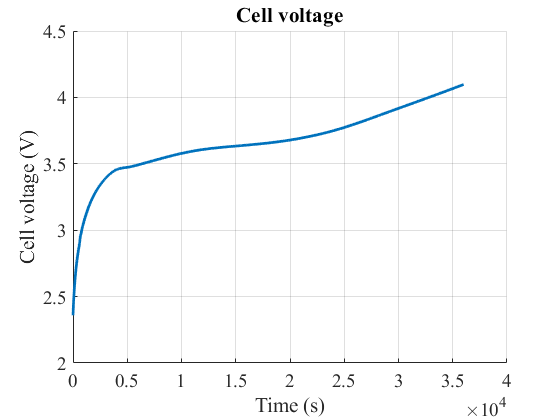



% Cell voltage
Fig = figure; % Create figure
Fig.Name= 'Cell voltage'; % Figure name
Fig.Color='white'; % Background colour
ax_ = axes('parent',Fig);
hold(ax_,'on'); % Active subplot
h_title=title ('Cell voltage'); % Set title font
plot(t,Cell_voltage,'Linestyle','-','Linewidth',2)
% Axis label
xlabel('Time (s)');
ylabel('Cell voltage (V)');
% - Grid
grid(ax_,'on'); % Display grid
set(ax_,'FontName','Times new roman','FontSize',14); % Fontname and fontsize
h_title.FontSize = 16; % Set title fontsize
hold(ax_,'off'); % Relase figure

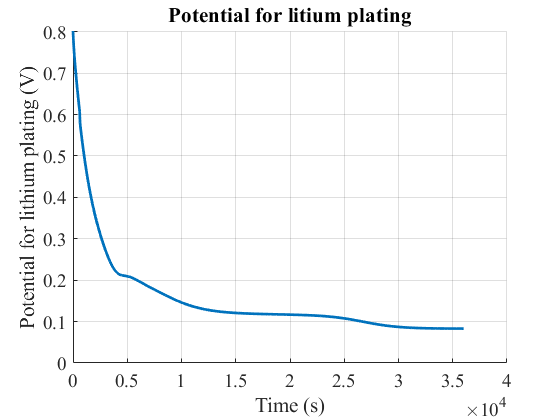


% Potential for lithium plating
Fig = figure; % Create figure
Fig.Name= 'Potential for litium plating'; % Figure name
Fig.Color='white'; % Background colour
ax_ = axes('parent',Fig);
hold(ax_,'on'); % Active subplot
h_title=title ('Potential for litium plating'); % Set title font
plot(t,PotentialPlating,'Linestyle','-','Linewidth',2)
% Axis label
xlabel('Time (s)');
ylabel('Potential for lithium plating (V)');
% - Grid
grid(ax_,'on'); % Display grid
set(ax_,'FontName','Times new roman','FontSize',14); % Fontname and fontsize
h_title.FontSize = 16; % Set title fontsize
hold(ax_,'off'); % Relase figure

# ***To know more***

Present work is the most simplistic representation of a lithium ion battery. More complex models exist:

- Single Particle Model (SPM). Electrodes are assumed to consist of spherical particles with identical size. Each electrode is represented with a single particle. Assumption is that the current distribution is uniform along the thickness of the porous electrode, that is the range of validity is also limited to low current, and/or thin electrodes, and/or high diffusivity/conductivity.

- Pseudo-2D (P2D) model. Model is 1D (along cell thickness) with in addition a secondary axis for the particle radius. Variations along thickness are modeled. This is the baseline of macroscale model, valuable for fast charge and thick electrode modeling (fit well with experimental data). Assumption is that particles are considered to be spherical, which is not adequate for some electrode materials, especially graphite.

- Microstructure scale model. This family of model meshes directly the 3D electrode geometry, thus any morphological assumption used in macroscale models are removed. Furthermore the impact of microstructure heterogenenity is considered, worthwile for investigating degradation mechanisms that are triggered by extremum values. However these models are limited to a small field of view, thus raising the issue of representativity, in addition to be much more CPU-expensive.

A. Jokar et al., Review of simpliﬁed Pseudo-two-Dimensional models of lithium-ion batteries, Journal of Power Sources 327 (2016) 44-55, [http://dx.doi.org/10.1016/j.jpowsour.2016.07.036](http://dx.doi.org/10.1016/j.jpowsour.2016.07.036)

Y. Zhao et al., A review on modeling of electro-chemo-mechanics in lithium-ion batteries, Journal of Power Sources 413 (2019) 259–283, [https://doi.org/10.1016/j.jpowsour.2018.12.011](https://doi.org/10.1016/j.jpowsour.2018.12.011)

function Io_a = Io_a_fct(Cs,Csmax,Ce,Ce_atrest,str)
x = Cs/Csmax; % State of charge
if strcmp(str,'Graphite (symmetric)')
    Io_a = 11 * sqrt(Ce/1000) * sqrt(Cs/Csmax) * sqrt(1-Cs/Csmax);
end
end

function OCP_a = OCP_a_fct(Cs,Csmax,str)
x = Cs/Csmax; % State of charge
if strcmp(str,'Graphite')
%     if x>=0.98
%         a = (1e-4 - 0.014763)/(1.1-0.98);
%         b = 0.014763-a*0.98;
%         OCP_a = a*x+b;
%    else
        a1 = -1.059423355572770E-02;
        a2 = 2.443615203087110E-02;
        a3 = -1.637520788053810E-02;
        a4 = -6.542365622896410E-02;
        a5 = -4.173226059293490E-02;
        a6 = - 4.792178163846890E-01;
        a7 = - 4.364293924074990E-02;
        a8 = - 8.241166396760410E-02;

        b1 = 1.453708425609560E-02;
        b2 = 5.464261369950400E-01;
        b3 = 5.639025014475490E-01;
        b4 = 5.960370524233590E-01;
        b5 = 1.787670587868640E-01;
        b6 = - 3.845707852011820E-03;
        b7 = 9.449231893318330E-02;
        b8 = 7.746685789572230E-02;

        c1 = 9.089868397988610E-05;
        c2 = 6.270508166379020E-01;
        c3 = 7.053886409518520E-02;
        c4 = 1.409966536648620E+00;
        c5 = 7.693844911793470E-02;
        c6 = 4.112633446959460E-02;
        c7 = -2.046776012570780E-02;
        c8 = 3.593817905677970E-02;

        U1 = a1*tanh((x - b1)/c1) + a2*tanh((x - b2)/c2) + a3*tanh((x - b3)/c3) + a4*tanh((x - b4)/c4) + a5*tanh((x - b5)/c5) + a6*tanh((x - b6)/c6) + a7*tanh((x - b7)/c7) + a8*tanh((x - b8)/c8) + 6.594735004847470e-1;

        d0 = - 5.037944982759270E+01;
        d1 = - 1.228217254296760E+01;
        d2 = - 6.906367679257650E+01;
        d3 = + 3.437968012320620E+00;
        d4 = + 3.322960033709470E+01;
        d5 = + 5.913206621637760E+01;
        d6 = 1.233160814852810E+02;
        d7 = + 8.252008712749000E+01;
        d8 = -1.731504647676420E+02;

        U2 = (((((((d8*x+d7)*x+d6)*x+d5)*x+d4)*x+d3)*x+d2)*x+d1)*x+d0;

        OCP_a = U1 + (U2 - U1) / (1.0 + exp(-1.0e2*(x - 1.02956203215198)));
%    end
end
end

function Io_c = Io_c_fct(Cs,Csmax,Ce,Ce_atrest,str)
x = Cs/Csmax; % State of charge
if strcmp(str,'NMC (asymmetric)')
    a0 = 0.303490440978371;
    a1 = 1.271944700013477;
    a2 = 4.420894220185683e+02;
    a3 = -5.783762746199664e+03;
    a4 = 3.822682327855755e+04;
    a5 = -1.416477460103355e+05;
    a6 = 3.113802647858406e+05;
    a7 = -4.169011915077865e+05;
    a8 = 3.347705415406199e+05;
    a9 = -1.485221335897379e+05;
    a10 = 2.803425068966447e+04;
    P = (((((((((a10*x+a9)*x+a8)*x+a7)*x+a6)*x+a5)*x+a4)*x+a3)*x+a2)*x+a1)*x+a0;
    Io_c = P * sqrt(Ce/Ce_atrest);
end
end

function OCP_c = OCP_c_fct(Cs,Csmax,str)
x = Cs/Csmax; % State of charge
if strcmp(str,'NMC')
    a14=-3.640118e3;
    a13=1.317658e4;
    a12=- 1.455742e4;
    a11=- 1.571094e3;
    a10=1.265631e4;
    a9=- 2.057809e3;
    a8=- 1.074374e4;
    a7=8.698113e3;
    a6=- 8.297905e2;
    a5=- 2.073765e3;
    a4=1.190223e3;
    a3=- 2.724852e2;
    a2=2.723409e1;
    a1=- 4.158277;
    a0=5.314736;
    A = (((((((((((((a14*x+a13)*x+a12)*x+a11)*x+a10)*x+a9)*x+a8)*x+a7)*x+a6)*x+a5)*x+a4)*x+a3)*x+a2)*x+a1)*x+a0;
    OCP_c = A - 5.573191e-4 * exp( 6.560241 * x^41.482093);
end
end   